# Comparing the decision boundaries of the DT, kNN, and LDA models

Team name: CONP Apps

Group Members: Chelsea, Omar, Nico, Peyton

Course: BME 3053C Computer Applications for BME

Term: Fall 2020

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

clc; clear; close all;

Loading the training and testing data

load TrainData.mat

Visualize Data

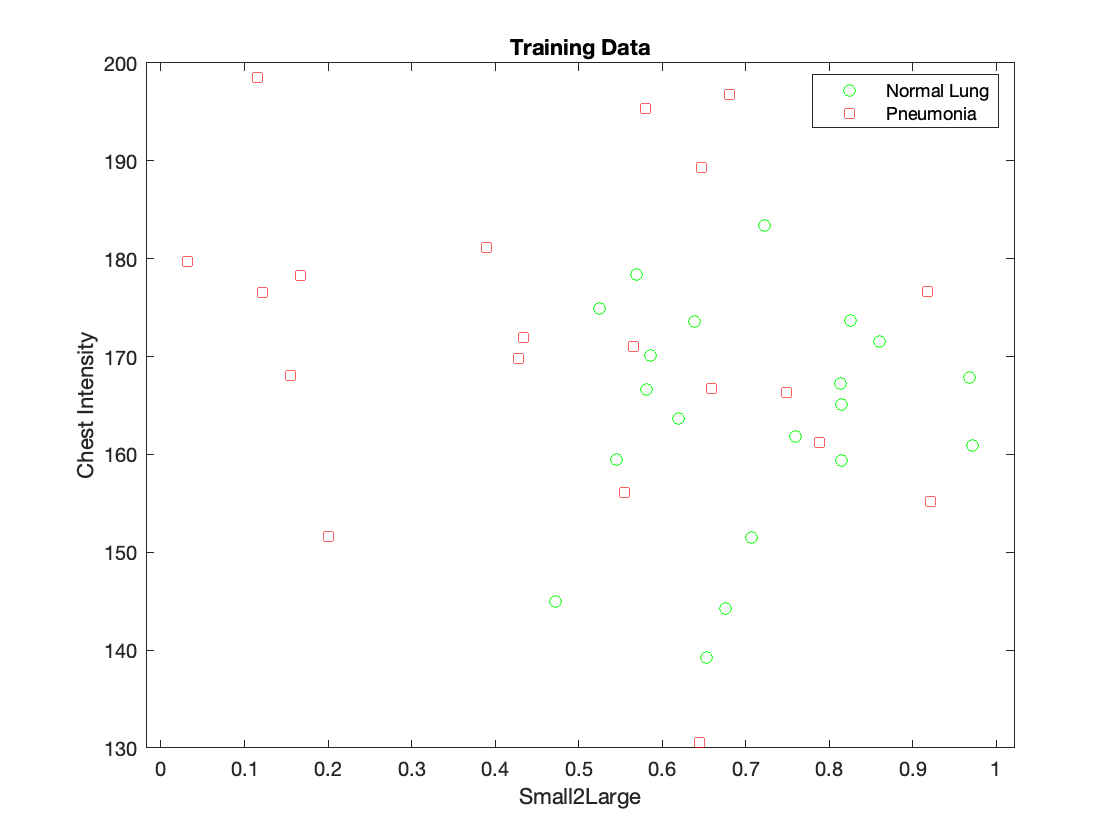

gscatter(TrainData.s2l, TrainData.Int, TrainData.State, 'gr', 'os')
title('Training Data');
xlabel('Small2Large');
ylabel('Chest Intensity');
legend('Normal Lung','Pneumonia');

DT

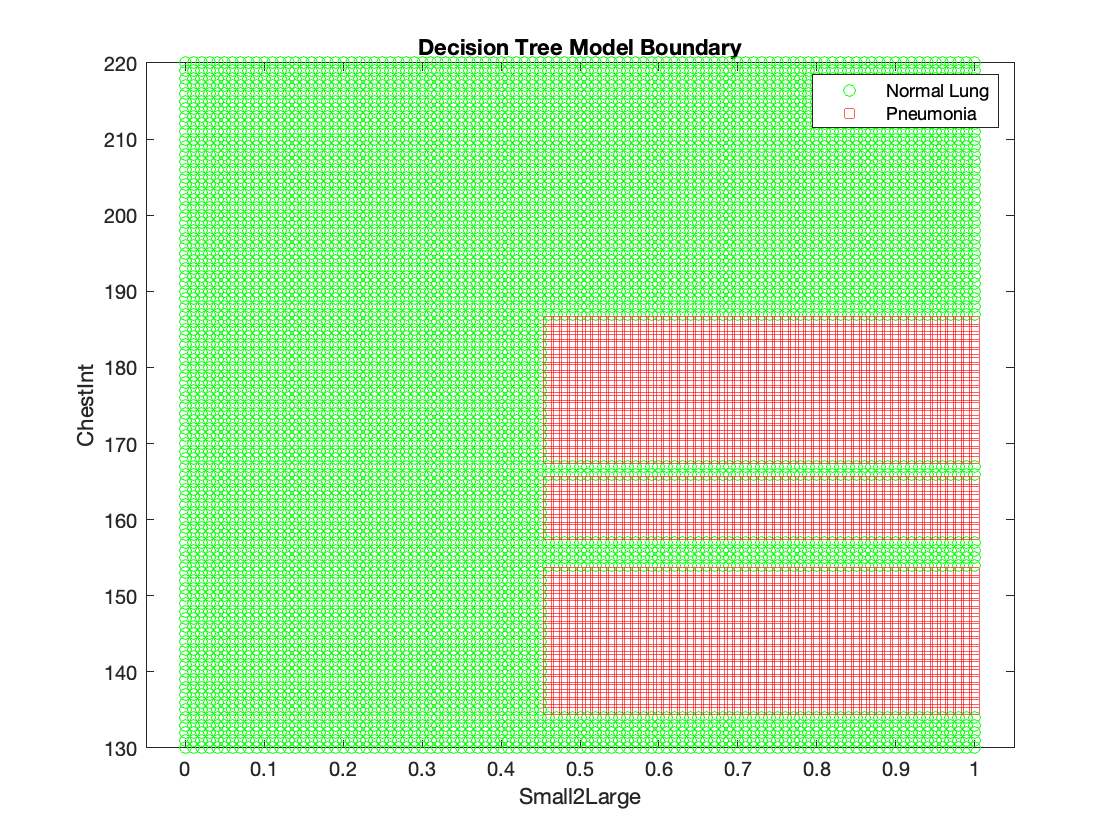

tree = fitctree([TrainData.s2l, TrainData.Int], TrainData.State);
[x,y] = meshgrid(0:0.01:1, 130:220);
x = x(:);
y = y(:);
z = predict(tree, [x,y]);
gscatter(x, y, z, 'gr', 'os');
title('Decision Tree Model Boundary');
xlabel('Small2Large');
ylabel('ChestInt');
legend('Normal Lung','Pneumonia');

kNN

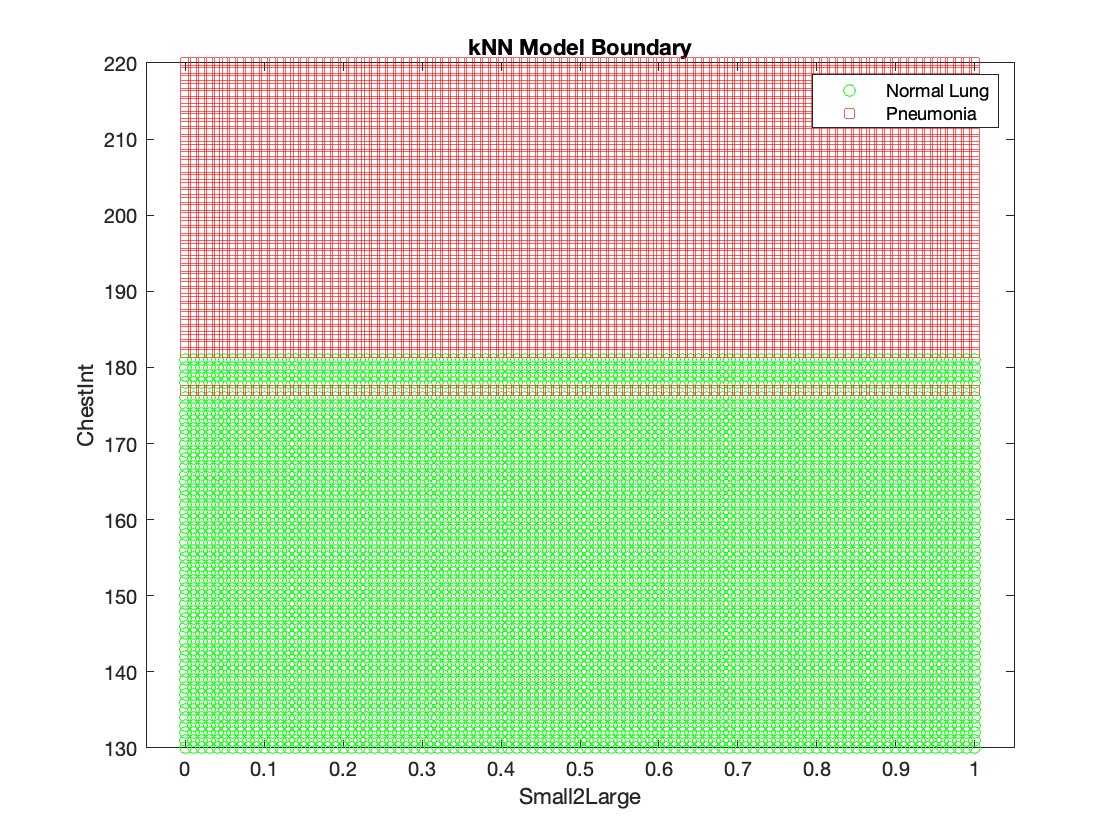

knnmodel = fitcknn([TrainData.s2l, TrainData.Int], TrainData.State, "NumNeighbors", 10);
[x,y] = meshgrid(0:0.01:1, 130:220);
x = x(:);
y = y(:);
z = predict(knnmodel, [x,y]);
gscatter(x, y, z, 'gr', 'os');
title('kNN Model Boundary');
xlabel('Small2Large');
ylabel('ChestInt');
legend('Normal Lung','Pneumonia');

LDA

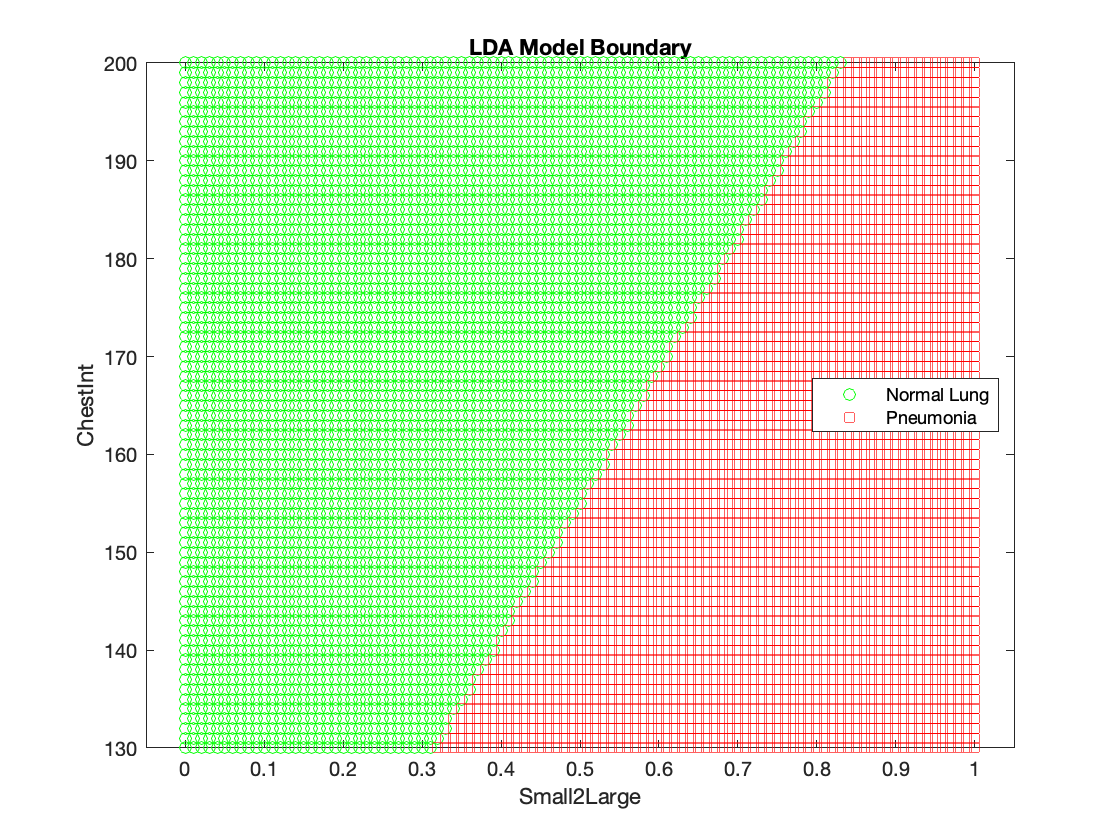

lda2 = fitcdiscr([TrainData.s2l, TrainData.Int], TrainData.State);
[x,y] = meshgrid(0:0.01:1, 130:200);
x = x(:);
y = y(:);
z = predict(lda2, [x,y]);
gscatter(x, y, z, 'gr', 'os');
title('LDA Model Boundary');
xlabel('Small2Large');
ylabel('ChestInt');
legend('Normal Lung','Pneumonia');